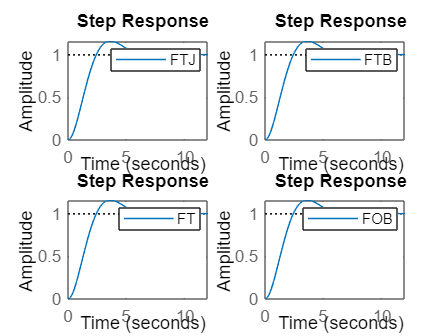

clear variables;

R=1;C=1;L=1;% atribuire de valori la parametrii sistemului

ftj=tf([0 0 1/L/C], [1 R/L 1/L/C]);% functia de transfer pt. FTJ
ftb=tf([0 R/L], [1 R/L 1/L/C]);% funcția de transfer pt. FTB

ft = tf([0 0 1/L/C], [1 1/R/C 1/L/C]); %functia de transfer pt ft
fob = tf(1, [1 1/R/C 1/L/C]); %functia de transfer pt fob

% răspunsul la treapta pentru FTJ -- circuit serie
subplot(2,2,1);step(ftj);legend('FTJ');
% răspunsul la treapta pentru FTB -- circuit serie
subplot(2,2,2);step(ftb);legend('FTB');

%raspuns la treapta pt ftj -- circuit paralel
subplot(2,2,3);step(ft);legend('FT');
%raspuns la treapta pt fob -- circuit paralel
subplot(2,2,4);step(fob);legend('FOB');